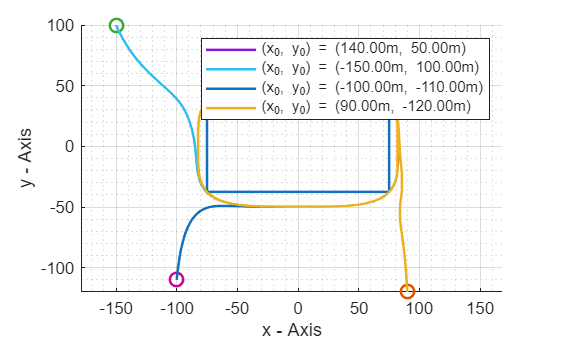

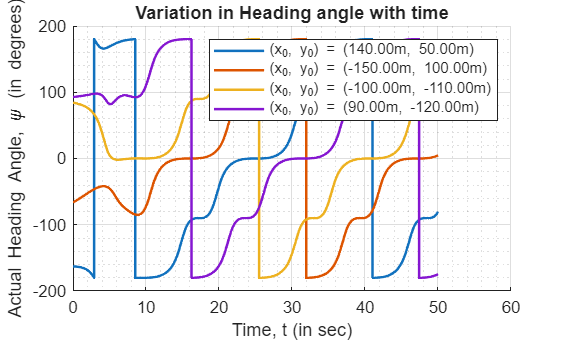

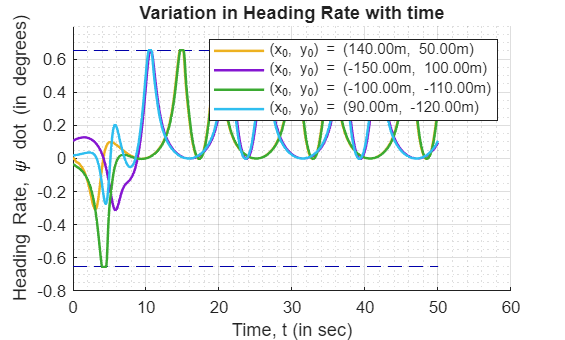

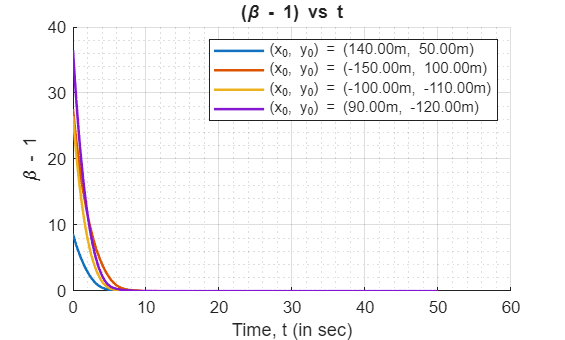

%Note always wrap the diffence of the angles, which is being supplied to
%the controller error.
clear;
clc;

% kMaxu = psiDotMax/va %m^-1
%Reactangle
l = 75;
m = 37.5;

%Corresponsing Lame' Curve for the rectangle, (n,a,b) calculated for
%minimum path length
n = 4.0631;
a = 82.4549;  %choose a > l
b = ((a^n * m^n)/(a^n - l^n))^(1/n);

simtime = 50;
h = 0.001;

%Initial Position of the UAV outside the Lame' curve
inipoout = [140,-150,-100,90;50,100,-110,-120];
inipsiout = [-2.8444,-1.1580,1.4731,1.6220];
inipsidotout = [-0.0099,0.1079,-0.0380,0.0172];

va = 15;
calculateAndDraw(l, m, n, a, b, simtime, h, va, inipoout, inipsiout, inipsidotout);

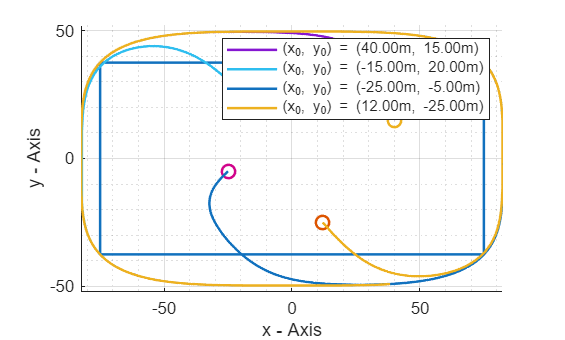

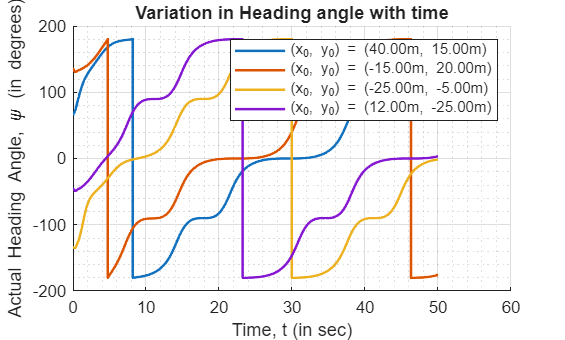

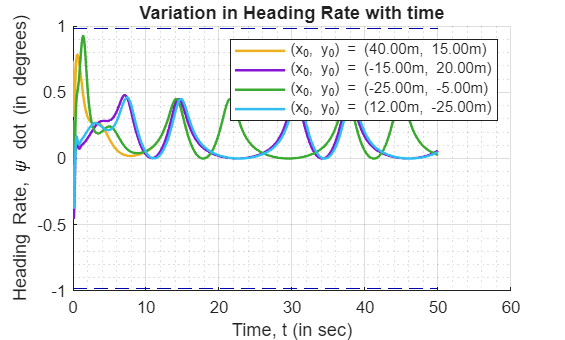

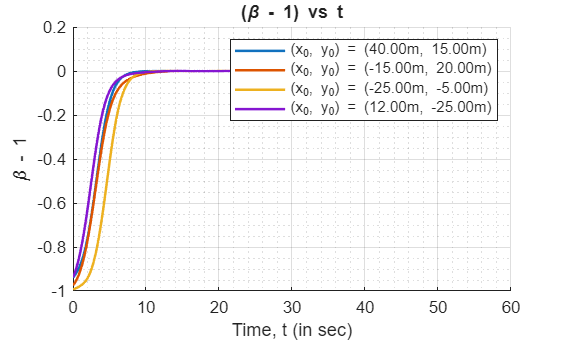

%Initial Position of the UAV inside the Lame' Curve
inipoin = [40,-15,-25,12;15,20,-5,-25];
inipsiin = [1.1380,2.3688,-2.3504,-0.7897];
inipsidotin = [0.7378,-0.0030,0.2880,-0.0492];

va = 10;
calculateAndDraw(l, m, n, a, b, simtime, h, va, inipoin, inipsiin, inipsidotin)


function calculateAndDraw(l, m, n, a, b, simtime, h, va, inipo, inipsi,inipsidot)
    g = 9.8;
    phiMax = 45*pi/180; %radians
    psiDotMax = g*tan(phiMax)/va; %radians/sec
    kMaxu = psiDotMax/va; %m^-1

    sz = size(inipo);
    pos = zeros([5,sz(2),simtime/h + 1]);
    plt = gobjects(1, sz(2));
    labels = cell(1, sz(2));
    
    ke = 0.5;
    kpsi = 100;
    kpsidot = 10;
    
    pos(1:2,1:sz(2),1) = inipo;
    figure;
    hold on;
    grid on; grid minor;
    axis equal;
    drawSquare(l,m);
    drawLameC(n,a,b);
    j = 1;
    while j <= sz(2)
        xa = pos(1, j, 1);
        ya = pos(2, j, 1);
        plot(xa, ya, 'o', markersize=8, linewidth=1.5);
        
        i = 2;
        for t = 0:h:simtime
            beta = abs(xa/a)^n + abs(ya/b)^n;
            %gradients,
            %where, f = |x / (a*beta^(1/n))|^n + |y / (b*beta^(1/n))|^n - 1
            fx = sign(xa)*n*abs(xa)^(n-1) / (a^n * beta);
            fy = sign(ya)*n*abs(ya)^(n-1) / (b^n * beta);
            fxx = n*(n-1)*abs(xa)^(n-2) / (a^n * beta);
            fyy = n*(n-1)*abs(ya)^(n-2) /(b^n * beta);
            
            psit = atan2(fx ,-fy);
            psio = pi/2 - asin(1/(1+ke*(beta-1)^2));
            psid = wrapToPi(psit + sign(beta - 1)*psio);
            
            %initially
            if t == 0 
                psi = inipsi(j);
            end
            
    
            psitdot = va*(fx*fyy*sin(psi) - fy*fxx*cos(psi))/(fx^2 + fy^2);
            psiodot = 2*ke*va*(fx*cos(psi) + fy*sin(psi))/((1+ke*(beta-1)^2)*sqrt((ke*(beta-1))^2 + 2*ke));
            psiddot = psitdot + sign(beta-1)*psiodot;
        
            %initially
            if t == 0
                psidot = inipsidot(j);
                pos(3:5,j,1) = [psi;psidot;beta-1];
            end
        
            [psi, psidot] = RK4psi(h,kpsi,kpsidot,psid,psi,psiddot,psidot);
            psidot = max(min(psidot, psiDotMax), -psiDotMax);

            xa = xa + va*cos(psi)*h;
            ya = ya + va*sin(psi)*h;
        
            pos(:,j,i) = [xa;ya;psi;psidot;beta-1];
            % if ~mod(i, 100)
            %     plot(pos(1,1:i), pos(2,1:i), linewidth = 1.5, color='#0099aa');
            %     pause(h/1000);
            % end
            i = i + 1;
        end
        
        plt(j) = plot(squeeze(pos(1,j,:)), squeeze(pos(2,j,:)), linewidth = 1.5);
        labels{j} = sprintf("(x_0, y_0) = (%.2fm, %.2fm)", pos(1,j,1), pos(2,j,1));
    
        j = j + 1;
    end
    
    legend(plt, labels);
    xlabel("x - Axis");
    ylabel("y - Axis");
    hold off;

    t = 0:h:simtime+h;
    %psi plotting
    figure;
    
    j = 1;
    hold on;
    grid on; grid minor;
    while j <= sz(2)
        plt(j) = plot(t, squeeze(pos(3,j,:))*180/pi, linewidth=1.5);
        labels{j} = sprintf("(x_0, y_0) = (%.2fm, %.2fm)", pos(1,j,1), pos(2,j,1));
        j = j + 1;
    end
    
    legend(plt, labels);
    xlabel("Time, t (in sec)");
    ylabel("Actual Heading Angle, \psi (in degrees)");
    title("Variation in Heading angle with time");
    hold off;

    %psidot plotting
    figure;
    
    j = 1;
    % plot(t, squeeze(pos(4,j,:)), linewidth=1.5);
    hold on;
    grid on; grid minor;
    plot([0, simtime+h], [psiDotMax, psiDotMax], '--', color='#0000aa');
    plot([0, simtime+h], [-psiDotMax, -psiDotMax], '--', color='#0000aa');
    while j <= sz(2)
        plt(j) = plot(t, squeeze(pos(4,j,:)), linewidth=1.5);
        labels{j} = sprintf("(x_0, y_0) = (%.2fm, %.2fm)", pos(1,j,1), pos(2,j,1));
        j = j + 1;
    end
    
    legend(plt, labels);
    xlabel("Time, t (in sec)");
    ylabel("Heading Rate, \psi dot (in degrees)");
    title("Variation in Heading Rate with time");
    hold off;

    %(beta-1) plotting
    figure;
    j = 1;
    hold on;
    grid on; grid minor;
    while j <= sz(2)
        plt(j) = plot(t, squeeze(pos(5,j,:)), linewidth=1.5);
        labels{j} = sprintf("(x_0, y_0) = (%.2fm, %.2fm)", pos(1,j,1), pos(2,j,1));
        j = j + 1;
    end
    
    legend(plt, labels);
    xlabel("Time, t (in sec)");
    ylabel("\beta - 1");
    title("(\beta - 1) vs t");
    hold off;

end



%supporting functions
function drawSquare(a, b)
    x = [a, -a, -a, a, a];
    y = [b, b, -b, -b, b];

    plot(x,y, linewidth=1.5);
end
function drawLameC(n,a,b)
    x1 = a:-0.01:0;
    x2 = -0.01:-0.01:-a;
    x = [x1 x2 flip(x2(2:end)) flip(x1)];
    
    y1 = (b/a) * (a^n - x1.^n).^(1/n);
    y2 = (b/a) * (a^n - (-x2).^n).^(1/n);
    y = [y1 y2  flip(-y2(2:end)) flip(-y1)];

    plot(x,y, linewidth=1.5);
end



function fn = gn(kpsi,kpsidot,psid,psi,psiddot,psidot)
    fn = kpsi*wrapToPi(psid - psi) + kpsidot*(psiddot - psidot);
end
function [psinext, psidotnext] = RK4psi(h,kpsi,kpsidot,psid,psi,psiddot,psidot)
    %since f = z; g = kpsi*(psid - psi) + kpsidot*(psiddot - psidot)
    %and also
    z = psidot;

    k1 = z;
    l1 = gn(kpsi, kpsidot, psid, psi, psiddot, z);
    k2 = z+ (h/2)*l1;
    l2 = gn(kpsi, kpsidot, psid, psi + (h/2)*k1, psiddot, z + (h/2)*l1);
    k3 = z+ (h/2)*l2;
    l3 = gn(kpsi, kpsidot, psid, psi + (h/2)*k2, psiddot, z + (h/2)*l2);
    k4 = z + h*l3;
    l4 = gn(kpsi, kpsidot, psid, psi + h*k3, psiddot, z + h*l3);

    psinext = wrapToPi(psi + (h/6)*(k1 + 2*k2 + 2*k3 + k4));
    psidotnext = z + (h/6)*(l1 + 2*l2 + 2*l3 + l4);
end